clc; format shortEng
% Materials
E = [77e9 73.6e9];
o_adm = [210e6 250e6];

Material_select = 2;
E_ = E(Material_select); o_adm_ = o_adm(Material_select);

m = 3 + 3.9863;
g = 9.81;

%Thickness
b = 30e-3;


% General Pivots
r = 0.006

r =      6.0000e-003


e = 0.00005

e =     50.0000e-006


k_piv =  2 * E_ * b * e^(2.5) / (9*pi*r^(0.5))

k_piv =     35.6440e-003


adm_piv = 3*pi*o_adm_*sqrt(r)/(4*E_*sqrt(e));
adm_piv_deg = rad2deg(adm_piv)

adm_piv_deg =      5.0233e+000


% Compensation de poids
%Lames
num_lames = 1;
springs_in_series = 7;
springs_in_parallel = 1;
L = 0.135

L =    135.0000e-003


ratio = 54;
h = L/ratio

h =      2.5000e-003


% ratio = L/h

rig_lame = (num_lames * E_ * b * h^3) / (L^3);
adm_lame = springs_in_series*(o_adm_ * L^2) /(3 * E_ * h)

adm_lame =     57.7785e-003


k_p = rig_lame/(springs_in_series) * springs_in_parallel

k_p =      2.0032e+003



precharge_dist_p = m*g/k_p

precharge_dist_p =     34.2134e-003


precharge_check_p = (precharge_dist_p >= 16e-3)&&(adm_lame >= precharge_dist_p + 16e-3)

precharge_check_p = logical
   1


precharge_force_p = k_p * precharge_dist_p;

precharge_adjustment_dist_poids = adm_lame - (precharge_dist_p + 16e-3)

precharge_adjustment_dist_poids =      7.5651e-003


% Compensation de Rigidity
syms k_r z Lr2
L1 = 250e-3;
L2 = 75e-3;
alpha = asin(z/L1);
beta = asin((2*L1*(1-cos(alpha)))/L2);
gamma1 = alpha+beta;
gamma2 = alpha-beta;
Lr1 = 0.1;

Table_type = "Table_Cols"

Table_type = "Table_Cols"

if Table_type == "Table_Lames"
    %Table a lames
    num_lames = 2;
    springs_in_series = 1;
    springs_in_parallel = 1;
    h = 0.000704
    ratio = Lr1/h %#ok<NASGU> 
    
    rig_t_lame = (num_lames * E_ * b * h^3) / (Lr1^3);
    adm_t_lame = springs_in_series*(o_adm_ * Lr1^2) /(3 * E_ * h)
    k_r_table = rig_t_lame/(springs_in_series) * springs_in_parallel
    charge_crit = (8*pi^2 * E_ * b * h^3)/(12*Lr1^2)
    
    lambda = (3*z^2)/(5*Lr1);
    Lr2 = eval(solve(adm_piv == asin(3*(16e-3)^2/(5*Lr1*Lr2)),Lr2))
    phi = asin(lambda/Lr2);
elseif Table_type == "Table_Cols"
    %Table a cols
    e_t = 0.00005
    r_t = 0.02
    
    rig_t_col = (8*E_*b*e_t^2.5)/(9*pi*Lr1^2*sqrt(r_t));
    adm_t_col = (3*pi*Lr1*o_adm_*sqrt(r_t))/(4*E_*sqrt(e_t))
    k_r_table = rig_t_col
    
    smallest_area = e_t*b*2;
    charge_crit = o_adm_
    
    lambda = Lr1 - sqrt(Lr1^2 - z^2);
    Lr2 = eval(solve(adm_piv == asin((Lr1 - sqrt(Lr1^2 - (16e-3)^2))/Lr2),Lr2))
    Lr2 = 20e-3
    phi = asin(lambda/Lr2);
end

e_t =     50.0000e-006


r_t =     20.0000e-003


adm_t_col =     16.0068e-003


k_r_table =      7.8092e+000


charge_crit =    250.0000e+006


Lr2 =     14.7133e-003


Lr2 =     20.0000e-003



% Rigidity Compensation Precharge
precharge_dist_r = 0.1;
L_r_rest = 0.04;
spring_length_ext = precharge_dist_r + L_r_rest

spring_length_ext =    140.0000e-003


res_var = sqrt(z^2 + (precharge_dist_r + L_r_rest - lambda)^2)-L_r_rest;

% pivots for rigidity comp springs
theta = asin(z/sqrt(z^2 + (precharge_dist_r + L_r_rest - lambda)^2));
theta_max = rad2deg(asin((16e-3)/sqrt((16e-3)^2 + (precharge_dist_r + L_r_rest - (Lr1 - sqrt(Lr1^2 - (16e-3)^2)))^2)))

theta_max =      6.5798e+000


rig_piv_e = 0.000053;
rig_piv_r = 0.0112;

k_rig_piv =  2 * E_ * b * rig_piv_e^(2.5) / (9*pi*rig_piv_r^(0.5))

k_rig_piv =     30.1799e-003


adm_rig_piv = 3*pi*o_adm_*sqrt(rig_piv_r)/(4*E_*sqrt(rig_piv_e));
adm_rig_piv_deg = rad2deg(adm_rig_piv)  % max angle subjected to ~6.165°

adm_rig_piv_deg =      6.6660e+000



rig_piv_smallest_area = rig_piv_e*b;

% Energies
ener_a = 0.5 * k_piv * alpha.^2;
ener_b = 0.5 * k_piv * beta.^2;
ener_g1 = 0.5 * k_piv * gamma1.^2;
ener_g2 = 0.5 * k_piv *gamma2.^2;
ener_poids = 0.5 * k_p * (z+precharge_dist_p).^2;
ener_r_table = 0.5 * k_r_table *z^2;
ener_r_col = 0.5 * k_piv * phi^2;
ener_r_res = 0.5 * k_r * res_var^2;
ener_r_piv = 0.5 * k_rig_piv * theta^2;
ener_masse = -m*g*z;
E_tot = 4*(ener_a + ener_r_col + ener_r_piv) + 2*(ener_b + ener_g1 + ener_g2 + ener_r_table + ener_r_res) + ener_poids + ener_masse;

Force = diff(E_tot);
Rigidity = diff(Force);

z = -15e-3:1e-4:15e-3;
k_r = 3530; % 3600 for table a cols % 4950 for table a lames
precharge_force_r = k_r*precharge_dist_r

precharge_force_r =    353.0000e+000


if Table_type == "Table_Cols"
    comp_contraint_t_cols = precharge_force_r/smallest_area
    crit_check = comp_contraint_t_cols <= charge_crit % 1 = all good, 0 = prob
elseif Table_type == "Table_Lames"
    crit_check = precharge_force_r <= charge_crit      % 1 = all good, 0 = prob
end

comp_contraint_t_cols =    117.6667e+006


crit_check = logical
   1


comp_contraint_rig_piv = precharge_force_r/rig_piv_smallest_area

comp_contraint_rig_piv =    222.0126e+006


crit_check = comp_contraint_rig_piv <= o_adm_

crit_check = logical
   1


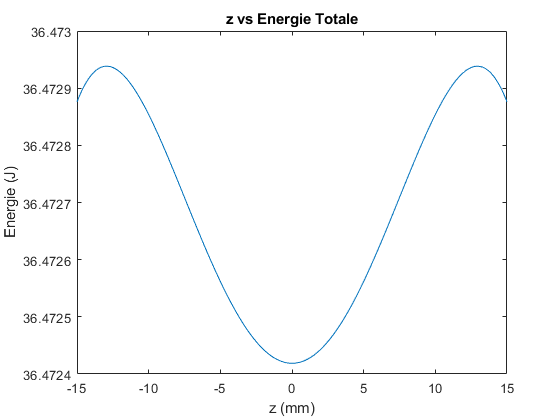

% Graphs

E_tot_num = eval(E_tot);
Force_num = eval(Force);
theta_num = eval(theta);
Rigidity_num = eval(Rigidity);
figure(1);
plot(z*1000, E_tot_num)
title("z vs Energie Totale");
xlabel("z (mm)");
ylabel("Energie (J)");

figure(2);
plot(z*1000, Force_num)
title("z vs Force Residuelle");
xlabel("z (mm)");
ylabel("Force (N)");
maxForce = max(Force_num)

maxForce =     65.0599e-003


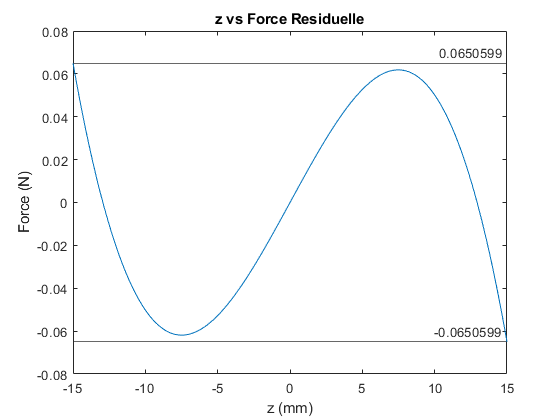

minForce = min(Force_num);
yline(maxForce,'-', maxForce);
yline(minForce,'-',minForce);

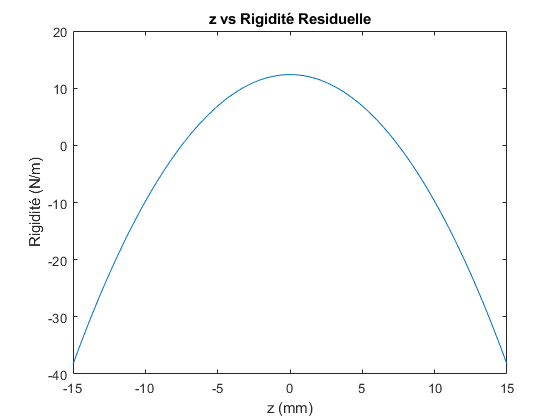

figure(3);
plot(z*1000, Rigidity_num)
title("z vs Rigidité Residuelle");
xlabel("z (mm)");
ylabel("Rigidité (N/m)");

% Ressort dimensioning in function of k
syms h L
assume(h > 100e-6);
assume(L < 200e-3);
num_lames = 1;
springs_in_series = 9;
springs_in_parallel = 1;

precharge_adjustment_dist_rig = 3e-3;

rig_form = k_r == (num_lames * E_ * b * h^3) / (L^3);
adm_form = (precharge_dist_r+precharge_adjustment_dist_rig)/springs_in_series == (o_adm_ * L^2) /(3 * E_ * h);

sol = solve(rig_form, adm_form, [h L]);
h = eval(sol.h)

h =      1.3820e-003


L = eval(sol.L)

L =    118.1895e-003


ratio = L/h

ratio =     85.5214e+000
